# TOPSIS 优劣解距离法

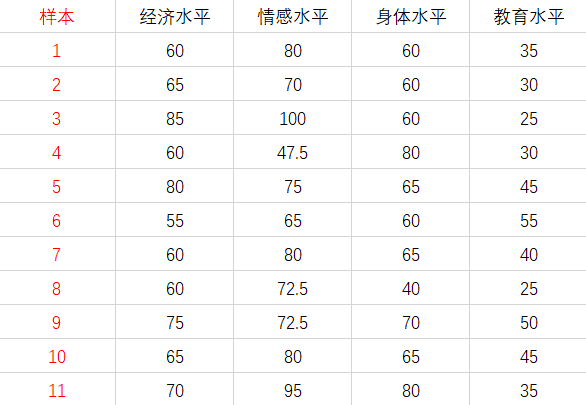

M = [60	80	60	35
65	70	60	30
85	100	60	25
60	47.5	80	30
80	75	65	45
55	65	60	55
60	80	65	40
60	72.5	40	25
75	72.5	70	50
65	80	65	45
70	95	80	35
]

M =    60.0000   80.0000   60.0000   35.0000
   65.0000   70.0000   60.0000   30.0000
   85.0000  100.0000   60.0000   25.0000
   60.0000   47.5000   80.0000   30.0000
   80.0000   75.0000   65.0000   45.0000
   55.0000   65.0000   60.0000   55.0000
   60.0000   80.0000   65.0000   40.0000
   60.0000   72.5000   40.0000   25.0000
   75.0000   72.5000   70.0000   50.0000
   65.0000   80.0000   65.0000   45.0000


## 正向化

[n,m] = size(M);
disp([num2str(n) '个评价对象   ' num2str(m) '个评价指标'])

11个评价对象   4个评价指标


disp('-----------------------指标正向化处理--------------------------')

-----------------------指标正向化处理--------------------------


column_position = input('输入亟处理的列向量： ')


column_position =

     []



disp('-1：极小型  0：中间型  1：区间型')

-1：极小型  0：中间型  1：区间型


type = input('输入这些列指标类型')


type =

     []



for i = 1:size(column_position,2)
    M(:,column_position(i)) = Forwardization(M(:,column_position(i)),type(i),column_position(i));
end
disp('正向化矩阵 M =  ')

正向化矩阵 M =  


disp(M)

   60.0000   80.0000   60.0000   35.0000
   65.0000   70.0000   60.0000   30.0000
   85.0000  100.0000   60.0000   25.0000
   60.0000   47.5000   80.0000   30.0000
   80.0000   75.0000   65.0000   45.0000
   55.0000   65.0000   60.0000   55.0000
   60.0000   80.0000   65.0000   40.0000
   60.0000   72.5000   40.0000   25.0000
   75.0000   72.5000   70.0000   50.0000
   65.0000   80.0000   65.0000   45.0000
   70.0000   95.0000   80.0000   35.0000



## 标准化

Standard_Martix = M./repmat(sum(M.*M).^0.5,n,1);
disp('标准化矩阵 Standard_Martix = ')

标准化矩阵 Standard_Martix = 


disp(Standard_Martix)

    0.2683    0.3120    0.2786    0.2710
    0.2906    0.2730    0.2786    0.2323
    0.3800    0.3900    0.2786    0.1936
    0.2683    0.1853    0.3715    0.2323
    0.3577    0.2925    0.3018    0.3485
    0.2459    0.2535    0.2786    0.4259
    0.2683    0.3120    0.3018    0.3098
    0.2683    0.2828    0.1857    0.1936
    0.3353    0.2828    0.3251    0.3872
    0.2906    0.3120    0.3018    0.3485
    0.3130    0.3705    0.3715    0.2710



## 赋权重

judge = input('是否赋权重？1是，0否: ');
if judge == 1
    weight = input(['输入' num2str(m) '个权重（向量形式）: ']);
    if abs(sum(weight)-1)<0.000001 && size(weight,1) == 1 && size(weight,2) == m
    else
        weight = input('权重有误，重新输入');
    end
else
    weight = ones(1,m) ./ m;
end

## 截距

intercept_max = sum([(Standard_Martix-repmat(max(Standard_Martix),n,1)) .^ 2],2) .^ 0.5;
intercept_min = sum([(Standard_Martix-repmat(min(Standard_Martix),n,1)) .^ 2],2) .^ 0.5;

## 得分

Unnormalized_Score = intercept_min ./ (intercept_max + intercept_min);
disp('最终得分： ')

最终得分： 


Standard_Score = Unnormalized_Score / sum(Unnormalized_Score)

Standard_Score =     0.0795
    0.0636
    0.0927
    0.0701
    0.1145
    0.0996
    0.0944
    0.0416
    0.1225
    0.1085


[Sort_Score,index] = sort(Standard_Score,'descend')

Sort_Score =     0.1225
    0.1145
    0.1131
    0.1085
    0.0996
    0.0944
    0.0927
    0.0795
    0.0701
    0.0636


index =      9
     5
    11
    10
     6
     7
     3
     1
     4
     2


## 绘图

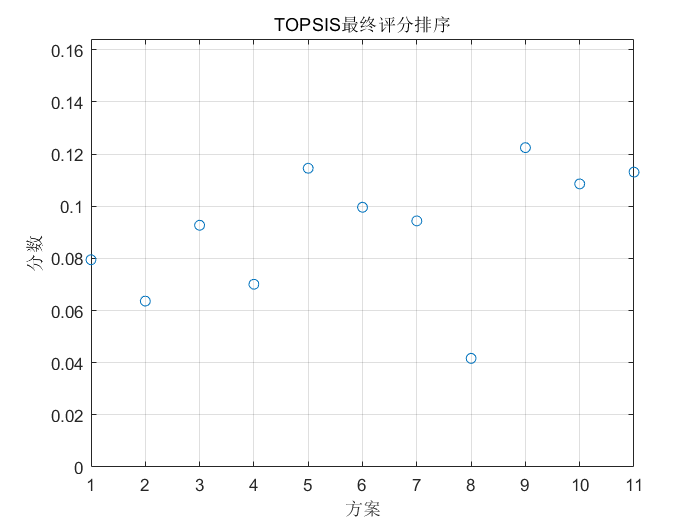

plot(index,Sort_Score,'o')
% plot(Sort_Score,'b-o')
xmin = 1;
xmax = size(Sort_Score,1);
ymin = 0;
ymax = max(Sort_Score) + min(Sort_Score);
axis([xmin xmax ymin ymax]);
grid on
xlabel('方案')
ylabel('分数')
title('TOPSIS最终评分排序')

## Forwardization 函数

function [position_x] = Forwardization(x,type,i)
    if type == -1
        disp(['第' num2str(i) '列是极小型，正在正向化'])
        position_x = Min2Max(x);
        disp(['第' num2str(i) '列极小型正向化处理完成'])
        disp('-------------------------------------------------')
    elseif type == 0
        disp(['第' num2str(i) '列是中间型'])
        best = input('请输入最佳的那一个值(中间的那个值)： ');
        position_x = Mid2Max(x,best);
        disp(['第' num2str(i) '列中间型正向化处理完成'])
        disp('-------------------------------------------------')
    elseif type == 1
        disp(['第' num2str(i) '列是区间型'])
        a = input('请输入区间的下界： ');
        b = input('请输入区间的上界： ');
        position_x = Inter2Max(x,a,b);
        disp(['第' num2str(i) '列区间型正向化处理完成'])
        disp('-------------------------------------------------')
    else
        disp('没有这种类型的指标，请检查Type向量中是否有除了-1、0、1之外的其他值')
    end
end

function [posit_x] = Min2Max(x)
    posit_x = max(x) - x;
end

function [posit_x] = Mid2Max(x,best)
    M = max(abs(x-best));
    posit_x = 1 - abs(x-best) / M;
end

function [posit_x] = Inter2Max(x,a,b)
    r_x = size(x,1);
    M = max([a-min(x),max(x)-b]);
    posit_x = zeros(r_x,1);
    for i = 1: r_x
        if x(i) < a
           posit_x(i) = 1-(a-x(i))/M;
        elseif x(i) > b
           posit_x(i) = 1-(x(i)-b)/M;
        else
           posit_x(i) = 1;
        end
    end
end